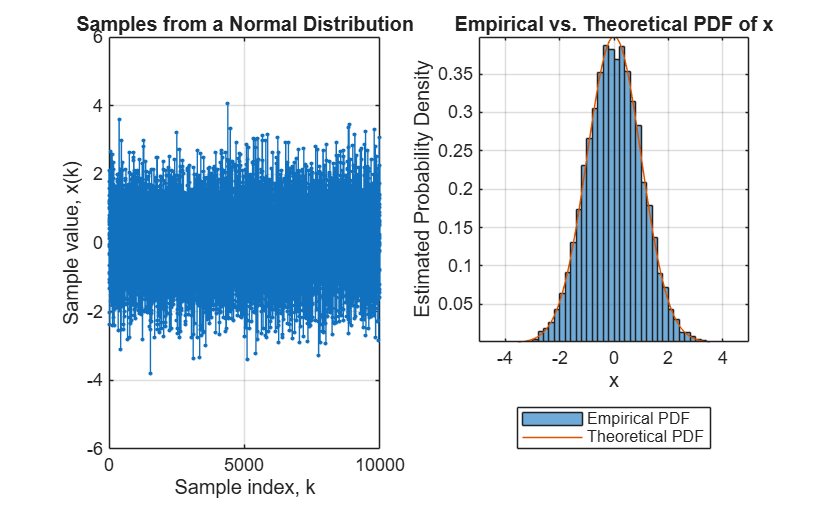

clear
clc

rng(12345);
N = 10000;
mu = 0;
sigma = 1;
x = mu + sigma*randn(N,1);
k = 0:(N-1);
R = 6*sigma;

figure;

subplot(1,2,1);
plot(k, x, '.-');
ylim([-R, R]);

title('Samples from a Normal Distribution');
xlabel('Sample index, k');
ylabel('Sample value, x(k)');
grid on;

subplot(1,2,2);
histogram(x, 'Normalization','PDF');
title('Empirical PDF of x');
xlabel('x');
ylabel('Estimated Probability Density');
grid on;

xl = xlim();
x_theory = linspace(xl(1), xl(2), 1000);
p_theory = exp(-0.5 * ((x_theory-mu)/sigma).^2) / (sigma * sqrt(2*pi));

hold("on");

plot(x_theory, p_theory);
xlabel('x');
ylabel('Estimated Probability Density');
title('Empirical vs. Theoretical PDF of x');
grid on;
legend('Empirical PDF', 'Theoretical PDF', 'Location', 'southoutside');
hold off;